# Presentation Models

clc; clear all; close all;
load TrainingData.mat;
load TestingData.mat;

Loads the Testing and Training Data from the table creation program

Model1 = fitcnb(TrainingData, "Type")

Model1 =   ClassificationNaiveBayes
            PredictorNames: {'Area'  'Density'  'Length'}
              ResponseName: 'Type'
     CategoricalPredictors: []
                ClassNames: {'A'  'M'  'P'}
            ScoreTransform: 'none'
           NumObservations: 60
         DistributionNames: {'normal'  'normal'  'normal'}
    DistributionParameters: {3×3 cell}


  Properties, Methods


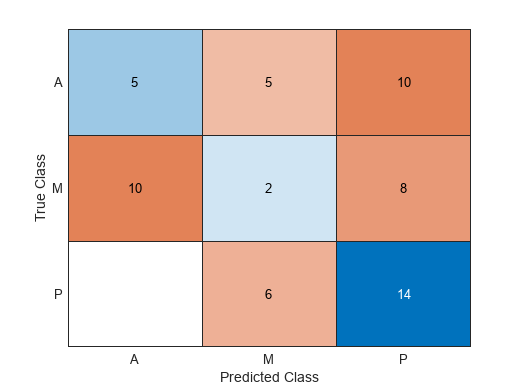


Prediction = predict(Model1, TestingData);
CorrectPrediction = Prediction == TestingData.Type;
Statedata = TestingData.Type;
Statedata = cellstr(Statedata);

confusionchart(Statedata, Prediction);

Accuracy = sum(CorrectPrediction) / numel(CorrectPrediction);

fprintf('Model Accuracy:');

Model Accuracy:

disp(Accuracy*100)

    35



The first model we ran was a Naive Bayes model. It had a 35% Accuracy.

Model3 = fitcdiscr(TrainingData, "Type")

Model3 =   ClassificationDiscriminant
           PredictorNames: {'Area'  'Density'  'Length'}
             ResponseName: 'Type'
    CategoricalPredictors: []
               ClassNames: {'A'  'M'  'P'}
           ScoreTransform: 'none'
          NumObservations: 60
              DiscrimType: 'linear'
                       Mu: [3×3 double]
                   Coeffs: [3×3 struct]


  Properties, Methods


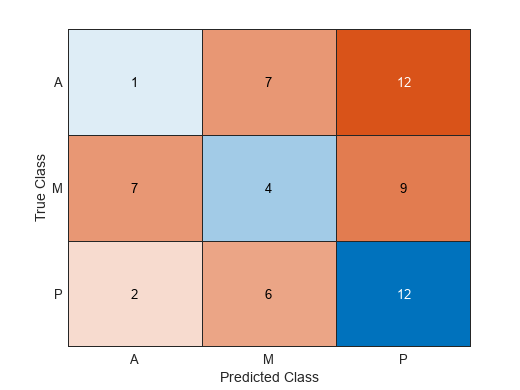


Prediction = predict(Model3, TestingData);
CorrectPrediction = Prediction == TestingData.Type;
Statedata = TestingData.Type;
Statedata = cellstr(Statedata);

confusionchart(Statedata, Prediction)

Accuracy = sum(CorrectPrediction) / numel(CorrectPrediction);

fprintf('Model Accuracy:');

Model Accuracy:

disp(Accuracy*100)

   28.3333



The second model we ran was a LDA model. It had a 28.33% accuracy.

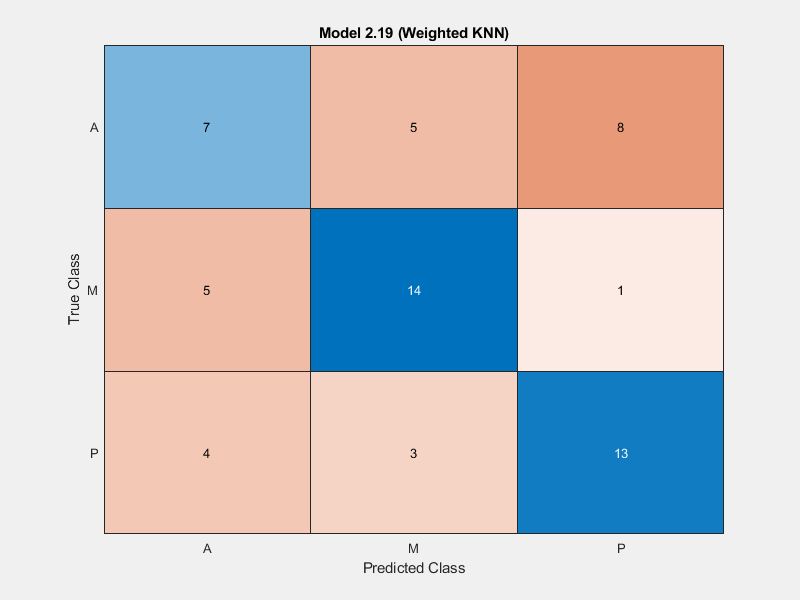

M21 = openfig("Model2Confusion.fig");
shg

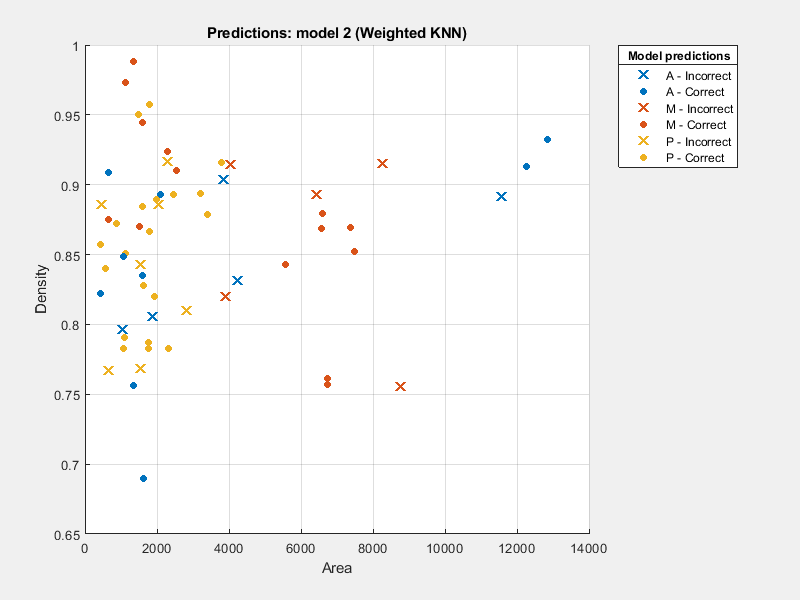


M22 = openfig("Model2ParallelCoordinates.fig");
shg

M23 = openfig("Model2Scatter.fig");
shg


M24 = openfig("Model2ValidationROC.fig");
shg

fprintf('Model Accuracy:');

Model Accuracy:

disp(56.7)

   56.7000



The third model we ran was a Weighted KNN model. It had a 56.7% accuracy.

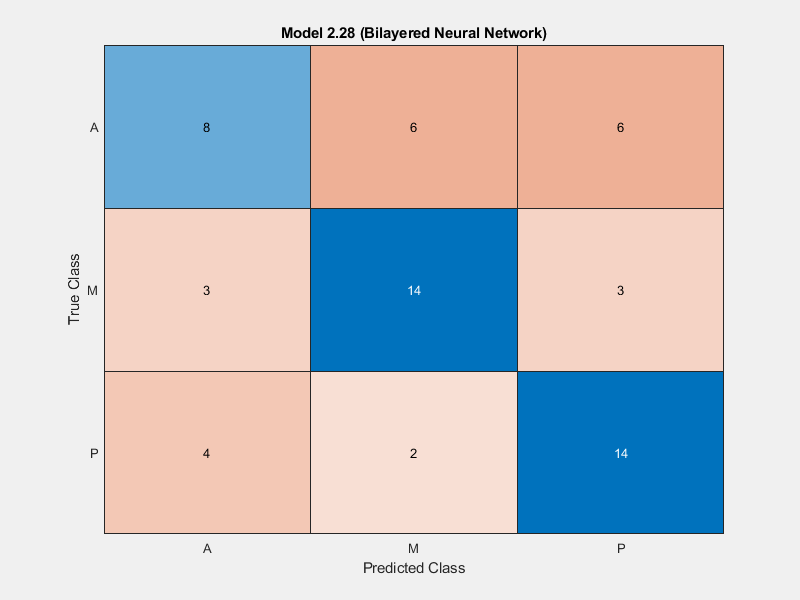

M41 = openfig("Model4Confusion.fig");
shg

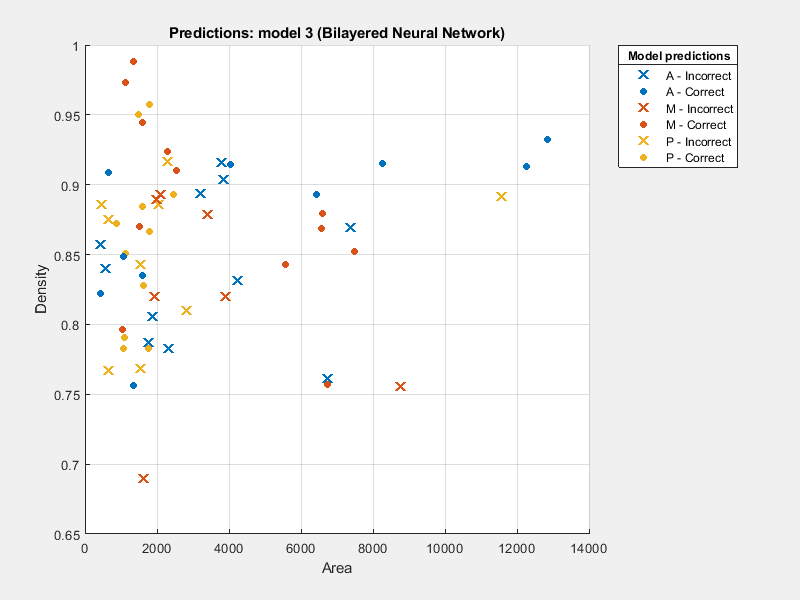


M42 = openfig("Model4ParallelCoordinates.fig");
shg

M43 = openfig("Model4Scatter.fig");
shg


M44 = openfig("Model4ValidationROC.fig");
shg

fprintf('Model Accuracy:');

Model Accuracy:

disp(60.0)

    60



The fourth model we ran was a Bilayered Neural Network model. It had a 60.0% accuracy.